## `Review and analysis of CO2 photoreduction kinetics`

#### `Warren A. Thompson, Eva S. Fernandez and M. Mercedes Maroto-Valer`

`Research Centre for Carbon Solutions (RCCS), School of Engineering & Physical Sciences, Heriot-Watt University, Edinburgh, EH14 4AS`

## Supplementary information S2-MedIt 

## A walk through of mean median multi-start trust-region 

## method for estimating nonlinear CO2 photoreduction

## kinetic model coefficients

Number of pages = 11

Number of figures = 3

See excellent MATLAB documentation for more information for the trust-region method

[https://uk.mathworks.com/help/optim/ug/constrained-nonlinear-optimization-algorithms.html](https://uk.mathworks.com/help/optim/ug/constrained-nonlinear-optimization-algorithms.html)

MATLAB R2018b used

### Data reported by Tan 

L.-L. Tan, W.-J. Ong, S.-P. Chai and A. R. Mohamed, Chemical Engineering Journal, 2017, 308, 248–255

- Extracted CH4 data at different partial pressures of CO2 from Figure 3 (a) using [WebPlotDigitizer](https://automeris.io/WebPlotDigitizer)

- Extracted CH4 data at different partial pressures of H2O from Figure 3 (b) using [WebPlotDigitizer](https://automeris.io/WebPlotDigitizer)

### Copy and paste these settings to run the script below

(Partial pressure CO2 (bar), partial pressure H2O (bar), CH4 production (umol.gcat-1.h-1), I (mW/cm2), 

reported  model coefficients and constraints used for mean median model in order of: k, alpha, 

KH2O and KCO2 )

experimental_settings_PCO2 = [0 0.25 0.5 0.75 0.9 1.01];

experimental_settings_PH2O = 0.043;

reported_CH4_production = [0 0.172 0.202 0.212 0.385 0.336];

I = 81;

reported_coefficients = [84.42 4.4E-2 8.070 1.93E-2];

lower_constraint = [0 0 0 0];

upper_constraint = [100 0.5 30 0.5];

#### Or use following if partial pressure CO2 was kept constant

experimental_settings_PCO2 = 0.9;

experimental_settings_PH2O = [0 0.043 0.088 0.173 0.312 0.565];

reported_CH4_production = [0 0.385 0.389 0.431 0.329 0.310];

I = 81;

reported_coefficients = [84.42 4.4E-2 8.070 1.93E-2];

lower_constraint = [0 0 0 0];

upper_constraint = [100 0.5 30 0.5];

## Data reported by Tahir

M. Tahir and N. S. Amin, Chemical Engineering Journal, 2013, 230, 314–327

- Extracted CH4 data at different partial pressures of CO2 from Figure 12 using [WebPlotDigitizer](https://automeris.io/WebPlotDigitizer)

- Assumed yield reported was for ten hour reaction

### Copy and paste these settings to run the script below

(Partial pressure CO2 (bar), partial pressure H2O (bar), CH4 production (umol.gcat-1.h-1), I (mW/cm2),

 reported  model coefficients and constraints used for mean median model in order of: k, alpha, 

KH2O and KCO2 )

experimental_settings_PCO2 = [0 0.019 0.039 0.059 0.079];

experimental_settings_PH2O = 0.0432;

reported_CH4_production = [0 67.70 77.48 73.47 65.29];

I = 150;

reported_coefficients = [500 6.0E-1 7.5E-1 30];

lower_constraint = [0 0 0 0];

upper_constraint = [200 0.8 25 50];

### Data reported by Khalizadeh

A. Khalilzadeh and A. Shariati, Solar Energy, 2018, 164, 251–261

- Extracted CH4 data at different partial pressures of CO2 from Figure 10 (a)

- Extracted CH4 data at different partial pressures of H2O from Figure 10 (b)

### Copy and paste these settings to run the script below

(Partial pressure CO2 (bar), partial pressure H2O (bar), CH4 production (umol.gcat-1.h-1), 

I (mW/cm2), reported  model coefficients and constraints used for mean median model 

in order of: k, alpha, KH2O, KCO2 and  n)

experimental_settings_PCO2 = [0 0.28 0.55 0.76 1.01];

experimental_settings_PH2O = 0.155;

reported_CH4_production = [0 19.84 23.53 28.15 24.92];                                

I = 85;

reported_coefficients = [6.47 6.5E-1 145.2 22.74 1.23];

lower_constraint  = [0 0 0 0 0 ];

upper_constraint = [80 0.7 200 40 2];

#### Or use following if partial pressure CO2 was kept constant

experimental_settings_PCO2 = 0.76;

experimental_settings_PH2O = [0.043 0.095 0.155 0.250 0.310];

reported_CH4_production = [22.15 24.92 28.15 26.30 22.61];

I = 85;

reported_coefficients =  [6.47 6.5E-1 145.2 22.74 1.23];

lower_constraint  = [0 0 0 0 0 ];

upper_constraint =[80 0.7 200 40 2];

## Please enter data and experimental settings used to fit the model

% Copy and paste experimental settings, production data and reported coeffients
% as code - highlight text and click "Code" icon in "LIVE EDITOR" ribbon
experimental_settings_PCO2 = [0 0.25 0.5 0.75 0.9 1.01];
experimental_settings_PH2O = 0.043;
reported_CH4_production = [0 0.172 0.202 0.212 0.385 0.336];
I = 81;
reported_coefficients = [84.42 4.4E-2 8.070 1.93E-2];
lower_constraint = [0 0 0 0];
upper_constraint = [100 0.5 30 0.5];

## Line changes optional - Assign two site LH and Sips kinetic model functions

if numel(experimental_settings_PH2O) == 1
    pressure_settings = ones(numel(experimental_settings_PCO2),2);
    pressure_settings(:,1) = pressure_settings(:,1).*experimental_settings_PCO2';
    pressure_settings(:,2) = pressure_settings(:,2).*experimental_settings_PH2O;
else
    pressure_settings = ones(numel(experimental_settings_PH2O),2);
    pressure_settings(:,1) = pressure_settings(:,1).*experimental_settings_PCO2;
    pressure_settings(:,2) = pressure_settings(:,2).*experimental_settings_PH2O';
end

% Two site kinetic model
% b(1) = k, b(2) = alpha, b(3) = KH2O and b(4) = KCO2

Two_site_LH_model = @(b,pressure_settings)...
                     (b(1).*I.^b(2).*(b(3).*pressure_settings(:,2).*b(4).*...
                     pressure_settings(:,1)))./...
                     ((1 + (b(3).*pressure_settings(:,2))...
                     + (b(4).*pressure_settings(:,1))).^2);

% Sips kinetic model
% b(1) = k, b(2) = alpha, b(3) = KH2O, b(4) = KCO2 and b(5) = n

Sips_kinetic_model = @(b,pressure_settings)...
                      (b(1).*(I.^b(2))).*(((pressure_settings(:,1).*b(4)).^...
                      (1./b(5))).*((pressure_settings(:,2).*b(3)).^(1./b(5))))...
                      ./((1 + ((pressure_settings(:,1).*b(4)).^(1./b(5))) +...
                      ((pressure_settings(:,2).*b(3)).^(1./b(5)))).^2);                   

## Line changes optional - Assign model and variables for plots

- To select model that median multi-start trust-region method will use

- Set number of columns for histogram plot

- Assign plot labels used by histogram and 3D bar plots

number_parameters = numel(lower_constraint);

if number_parameters == 4
    
    % Assign model
    kinetic_model = Two_site_LH_model;
    
    % Assign number of columns for histogram subplot 
    number_columns = 2;
    
    % Assign plot labels
    x_label = ["k (\mumol.g_{cat}^{-1}.h^{-1})" "\alpha" "K_{H_{2}O}" + ...
               "(bar^{-1})" "K_{CO_2} (bar^{-1})"];
    
else
    
    % Assign model
    kinetic_model = Sips_kinetic_model;
    
    % Assign number of columns for histogram subplot 
    number_columns = 3;
    
    % Assign plot labels
    x_label = ["k (\mumol.g_{cat}^{-1}.h^{-1})" "\alpha" "K_{H_{2}O}" + ...
               "(bar^{-1})" "K_{CO_2} (bar^{-1})" "n"];
    
end

## Please enter values 

- For number of loops median multi-start trust -region method will run 

- Number of iterations per median loop

- Number of multi-start points 

% Set the number of times the median iteration method will loop, Set to 1 if
% you are not interested in calculating the standard deviation of the
% median values and only want one set of median coefficient estimates
number_for_std_deviation_calculation = 10;   

% Set the number times the multi-start trust-region method will iterate
% within number of loops set above 
number_median_iterations = 50;            

% Set number of starting points for multi-start algorithm
no_multi_start_points = 10; 

## Line changes optional - Median multi-start trust-region method

- This is the median multi-start trust-region method

- After each multi-start iteration, the median of the coefficients estimated will be saved in an array

% Assign empty data array to record the median value after each loop of
% multi-start trust-region iterations is complete
multiple_median_approach_values = [];
all_multistart_values = [];

% Assign empty data array to record the coefficient estimates for each 
% multi-start solution
multistart_model_values        = [];


for std_deviation_run = 1:number_for_std_deviation_calculation
     
    for median_run = 1:number_median_iterations
        
        % Randomly select intial starting point values between upper and 
        % lower constraint values
        Random_starting_point_values = (upper_constraint-lower_constraint)....
                                        *rand(1,1) + lower_constraint;

        problem = createOptimProblem('lsqcurvefit','x0',...
                                     Random_starting_point_values,'objective',...
                                     kinetic_model,'lb',lower_constraint,...
                                     'ub',upper_constraint,'xdata',...
                                     pressure_settings,'ydata',...
                                     reported_CH4_production');

        ms = MultiStart('Display','off');
        [xmulti,errormulti,flagm,outptm,manyminsm] = run(ms,problem,...
                                                         no_multi_start_points);
        
        multistart_model_values(median_run,1:numel(lower_constraint)) = xmulti;
                     
    end
 
 % Lets collect the coefficient values based on median approach for each round   
 multiple_median_approach_values(std_deviation_run,...
 1:numel(lower_constraint)) = median(multistart_model_values);
 
 % Let's collect all of the multistart values for plotting histograms later
 all_multistart_values = [all_multistart_values;multistart_model_values];
 
end

## Line changes optional - What is the mean and standard deviation of  

## coefficients from the median multi-start approach?

In order of k, alpha, KH2O and KCO2 for two site and k, alpha, KH2O, KCO2 and n for Sips

Repeat the 'Line changes optional - Median multi-start trust-region method' and this chunk of code to see that the method is reproducible 

% Calculate mean and standard deviation of coefficients from median
% multi-start approach

if number_for_std_deviation_calculation == 1
    disp(['Not enough median values to calcuate standard deviation' ...
          ' and mean. Set ''number_for_std_deviation_calculation" > 1'])
    disp(['Coefficient values from median approach after' ...
          ' one iteration loop used  shown below:'])
    mean_median_coefficients = multiple_median_approach_values      
else
    disp('The standard deviation of the median coefficients are:')
    std_dev_median_coefficients = std(multiple_median_approach_values)
    disp('The mean of the median coefficients are:')
    mean_median_coefficients    = mean(multiple_median_approach_values)
end

The standard deviation of the median coefficients are:


std_dev_median_coefficients =     0.7613    0.0086    0.1277    0.0016


The mean of the median coefficients are:


mean_median_coefficients =    18.0480    0.0998    1.7783    0.3211


## Line changes optional - Plot histograms of the coefficient values with mean median value as dotted red line       

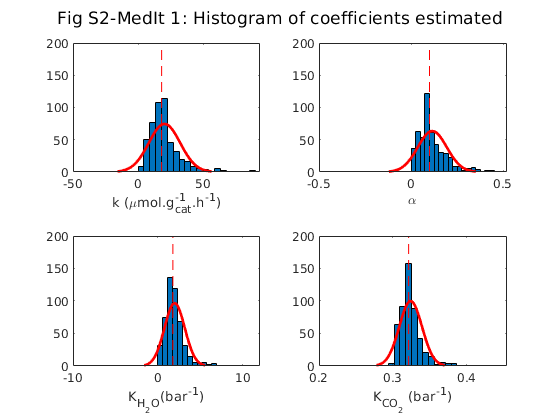

figure;

% Set maximum histogram plot height, will need to increase for higher
% values set for: 'number_for_std_deviation_calculation' and/or 
% 'number_median_iterations'
max_height=200; 
 
% Plot histogram and median line for k coefficient estimates 
subplot(2,number_columns,1); 
histfit(all_multistart_values(:,1),20); xlabel(x_label(1), 'FontSize', 20);
hold on
p = line([mean_median_coefficients(1,1),mean_median_coefficients(1,1)],...
         [0,max_height],'Color','r','LineStyle','--');

% Plot histogram and median line for alpha coefficient estimates 
subplot(2,number_columns,2); 
histfit(all_multistart_values(:,2),20); xlabel(x_label(2), 'FontSize', 20);
hold on
p = line([mean_median_coefficients(1,2),mean_median_coefficients(1,2)],...
         [0,max_height],'Color','r','LineStyle','--');

% Plot histogram and median line for KH2O coefficient estimates 
subplot(2,number_columns,3); 
histfit(all_multistart_values(:,3),20); xlabel(x_label(3), 'FontSize', 20);
hold on
p = line([mean_median_coefficients(1,3),mean_median_coefficients(1,3)],...
         [0,max_height],'Color','r','LineStyle','--');

% Plot histogram and median line for KCO2 coefficient estimates 
subplot(2,number_columns,4); 
histfit(all_multistart_values(:,4),20); xlabel(x_label(4), 'FontSize', 20); 
hold on
p = line([mean_median_coefficients(1,4),mean_median_coefficients(1,4)],...
         [0,max_height],'Color','r','LineStyle','--');

if numel(x_label) == 5
    
    % Plot histogram and median line for n coefficient estimates 
    subplot(2,number_columns,5); 
    histfit(all_multistart_values(:,5),20); xlabel(x_label(5), 'FontSize', 20); 
    hold on
    p = line([mean_median_coefficients(1,5),mean_median_coefficients(1,5)],...
             [0,max_height],'Color','r','LineStyle','--');    

end

sgtitle('Fig S2-MedIt 1: Histogram of coefficients estimated')

## Line changes optional - Plot the mean median model, recorded model and recorded data points 

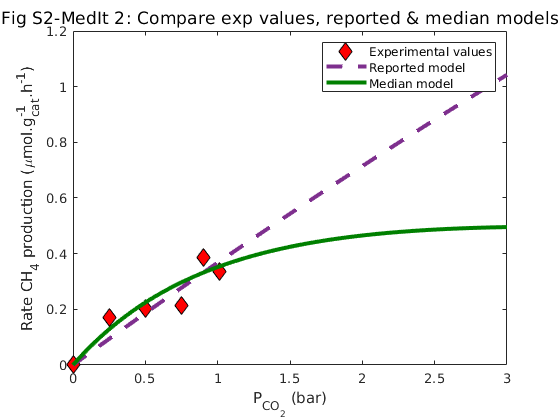

if numel(experimental_settings_PH2O) == 1
    
    % Create CO2 partial pressure values to fit with models 
    model_settings_PCO2 = linspace(0,3,100)';
    
    % Use constant experimental H2O partial pressure setting to fit with
    % model
    model_settings_PH2O = ones(numel(model_settings_PCO2),1).*...
                               experimental_settings_PH2O;
    
    % Combine CO2 and H2O partial pressures into matrix to fit with model 
    model_pressure_settings = [model_settings_PCO2 model_settings_PH2O];
    
    % Estimate CH4 production using reported and mean median models
    CH4_production_reported_model = kinetic_model(reported_coefficients,...
                                                  model_pressure_settings);
    CH4_production_median_model   = kinetic_model(mean_median_coefficients,...
                                                  model_pressure_settings);

    % Plot experimental values, reported and mean median model  
    figure;
    plot(experimental_settings_PCO2,reported_CH4_production,...
        'Color', 'r','Marker','diamond','LineStyle','none','MarkerSize',10,...
        'MarkerFaceColor','r','MarkerEdgeColor','k')
    hold on;
    plot(model_settings_PCO2, CH4_production_reported_model,...
        'Color',[0.4940, 0.1840, 0.5560],'Marker','none','LineStyle','--',...
        'LineWidth',3)
    hold on;
    plot(model_settings_PCO2, CH4_production_median_model,...
        'Color', [0, 0.5, 0],'Marker','none','LineStyle','-','LineWidth',3)
    legend('Experimental values', 'Reported model','Median model');
    
    xlabel('P_{CO_2} (bar)','FontWeight','bold')
    ylabel('Rate CH_4 production (\mumol.g_{cat}^{-1}.h^{-1})','FontWeight',...
           'bold')

else
   
    % Create H2O partial pressure values to fit with models 
    model_settings_PH2O = linspace(0,1,100)';
    
    % Use constant experimental CO2 partial pressure setting to fit with
    % model
    model_settings_PCO2 = ones(numel(model_settings_PH2O),1).*...
                               experimental_settings_PCO2;
    
    % Combine CO2 and H2O partial pressures into matrix to fit with model 
    model_pressure_settings = [model_settings_PCO2 model_settings_PH2O];
    
    % Estimate CH4 production using reported and mean median models
    CH4_production_reported_model = kinetic_model(reported_coefficients,...
                                                  model_pressure_settings);
    CH4_production_median_model   = kinetic_model(mean_median_coefficients,...
                                                  model_pressure_settings);

    % Plot experimental values, reported and mean median model  
    figure;
    plot(experimental_settings_PH2O,reported_CH4_production,...
        'Color', 'r','Marker','diamond','LineStyle','none','MarkerSize',10,...
        'MarkerFaceColor','r','MarkerEdgeColor','k')
    hold on;
    plot(model_settings_PH2O, CH4_production_reported_model,...
        'Color',[0.4940, 0.1840, 0.5560],'Marker','none','LineStyle','--',...
        'LineWidth',3)
    hold on;
    plot(model_settings_PH2O, CH4_production_median_model,...
        'Color', [0, 0.5, 0],'Marker','none','LineStyle','-','LineWidth',3)
    legend('Experimental values', 'Reported model','Median model');
    xlabel('P_{H_{2}O} (bar)','FontWeight','bold')
    ylabel('Rate CH_4 production (\mumol.g_{cat}^{-1}.h^{-1})','FontWeight',...
            'bold')

end
sgtitle('Fig S2-MedIt 2: Compare exp values, reported & median models')

## Line changes optional - How do the estimated reported and mean median model coefficient estimates compare?

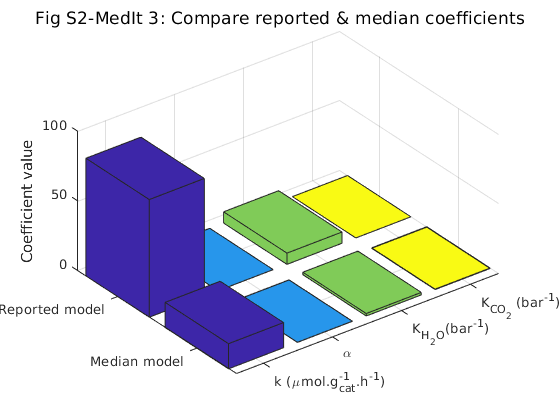

figure;
bar3([reported_coefficients;mean_median_coefficients])
xticklabels(x_label)
yticklabels({'Reported model', 'Median model'})
zlabel('Coefficient value')
sgtitle('Fig S2-MedIt 3: Compare reported & median coefficients')